***RE_CS_221021_F_RadiatorCalculator.mlx***

Documento propiedad del ISC FS Racing team, dpt. de Refrigeración, para el proyecto de coche eléctrico. Presente temporada 2023, coche en desarrollo: IFS-05. Herramienta de predicción analítica estática de radiadores.

**Objetivo: **Deducir las temperaturas del líquido refrigerante (agua) con un radiador determinado. Para determinar su viablidad, pues se limita por estas. Deberá hacerse correlación con las temperaturas de los aparatos refrigerados.

Aparatos refrigerados: Motor EMRAX 228 e inversor BAMOCAR B3.

**Procedimiento:** Se parte de las dimensiones geométricas del radiador, temperatura del entorno, velocidad del aire, caudal de agua y calor a disipar. Se suponen unas temperaturas iniciales en el líquido refrigerante para empezar la interación. Cuanto más cerca de  las estáticas finales mas rápido convergerá (puede no converger).

Observación: Se deducir temperaturas térmicas en régimen permanente. Quedan lejos de las temperturas que se darán realmente. Realizar estimaciones oportunas.

**Criterios de validez de operación:**

- Temperatura máxima fluido inversor: 65ºC

- Temperatura máxima fluido entrada motor: 50ºC

clc; clear;

#### ***Condiciones de contorno***

Retorno ínidice: INDICE

Introducir los datos sobre el punto de operación en el que se evalua el radiador. Realizar estimaciones necesarias para determinarlo.

%Velocidad aerodinámica:
%Velocidad media del coche ponderada a velocidad por el radiador. Según
%ensayos de flujo lire en radiadores. En [m/s].
u_coche_mean=60/3.6;
load("RE_CS_220901_AFactorVelocidadCoche.mat","B");
u_air=B*u_coche_mean;
clear B u_coche_mean;
%u_air=u_air*[0.6:0.01:1.4];            %VECTORIZABLE

%Caudal de agua:
%Recomendad por datasheet del motor. Corresponde realizar un estudio 
%hidráulico. En [m3/s].
Q_wat=8/1000/60;
%Q_wat=Q_wat*[0.6:0.01:1.4]';           %VECTORIZABLE

%Temperatura ambiental del aire:
%Se emplea temperatura media en Barcelona en el mes de agosto. Deberá
%hacerse un estudio del destino de competición. En [Cº]
T_air_in=30;
%T_air_in=[27:1:35];                    %VECTORIZABLE

%Número de radidores en paralelo:
%Para considerar dos radiadores iguales en paralelo en el sistema evaluado.
%Se considerará el N veces el area de radiador y 1/N veces el caudal agua.
N=2;

%Calor generado a disipar:
%El dato acutal sale del ensayo de rotor bloqueado de 110A. Se supone que
%el calor generado en el ensayo solo ocurren en el inversor. Se aproxima un
%calor total (motor+inversor) por las pérdidas máximas de cada aparato.
%Debe hacerse un ensayo en el coche real para tener buenos resultados.

%Pérdidas máximas en cada aparato, del datasheet [W].
q_MaxLossInverter=2e3;
q_MaxLossMotor=42e3*8e-2;

%Calor generado en el ensayo de rotor bloqueado 110A [W] y factor de
%seguridad empleado.
load("RE_CS_220202_AGeneratedQ.mat");
n_sec=2.4;

%Calor total por la ponderación comentada [W].
q_gen=(n_sec*(q_gen+q_MaxLossInverter*q_gen/q_MaxLossMotor))

q_gen = 3.0625e+03

%q_gen=q_gen*[0.5:0.05:1.5]';           %VECTORIZABLE

%Por interés, proporción calor del motor frente total.
relation=q_MaxLossMotor/(q_MaxLossMotor+q_MaxLossInverter)

relation = 0.6269

clear n_sec q_MaxLossMotor q_MaxLossInverter relation;

#### ***Datos del radiador evaluado***

Retorno ínidice: INDICE

Realizar las interpretaciones de geometría que se consieren oportunas.Los datos actuales son considerando los conductos como rectangulares. Puede afinarse empleando secciones reales y areas superficiales.

%Todas las dimensiones en unidades de metros [m].

%Datos del lado caliente de agua:
%Dimensiones de ancho, alto, y largo de los conductos de agua caliente.
W_wat=1e-3;
H_wat=13.2e-3;
L_wat=240e-3;
%Número de conductos de agua.
N_wat=12;
%N_wat=N_wat*[0.6:0.1:1.6];         %VECTORIZABLE

%Cálculos hidráulicos del lado caliente de agua:
%Area, perímetro y diámetros hidráulico.
Ah_wat=W_wat*H_wat;
Ph_wat=2*W_wat+2*H_wat;
Dh_wat=4*Ah_wat/Ph_wat;

%Area convectiva de intercambio para el lado de agua caliente. Se ha de
%considerar el número N de radiadores y cada conducto de agua en el rad.
Acon_wat=N*(N_wat*Ph_wat*L_wat);

%Velocidad de agua por los conductos.
u_wat=Q_wat./(N*Ah_wat*N_wat);

%Datos del lado frio de aire
%Dimensiones de ancho, alto y profundo de los conducto de aire frio.
W_air=236e-3;
H_air=7.2e-3;
L_air=48e-3;
%Número de conductos de aire.
N_air=12;                           %VECTORIZABLE

%Datos dimensionales aletas de los tubos, donde el ancho W_fin es el espesor del
%material de la aleta. Se considera la longitud total por su angulación.
W_fin=0.4e-3;
ang_fin=13.65; %[deg]
H_fin=H_air/(2*cosd(ang_fin));
L_fin=L_air;
%Distancia de separación entre la base de las aletas.
S_fin=1.7e-3;
%Número de aletas en un solo conducto del lado frio de aire. Será el número de 
%aletas reales por dos, para hacer la consideracion de extremo adiabático.
N_fin=2*(W_air)/S_fin;
clear ang_fin;

%Conductividad térmica del material metálico del radiador. El dato amtual
%empleado en la conductividad de un cobre arbitrario. En [W/m·K]
k_rad=389;

#### Carga hipótesis térmica inicial

Retorno ínidice: INDICE

Se emplean para iniciar el proceso iterativo. Aunque la convergencia es rápida, conviene que sean lo más proximas al resultado esperdo. Valores inverosímiles pueden dar lugar a errores.

%Temperatuas del lado de agua y superficial del radiador. T_wat_in=40;
T_wat_in=30;
%T_wat_in=[30:1:50];
T_wat_out=35;
T_sup=37;

Ah_air=W_air*H_air;
T_air_eval=T_air_in+5;
[ro_air,cp_air,~,~,~]=fair_prop(T_air_eval);
C_air=(N*N_air.*Ah_air*u_air).*ro_air.*cp_air;
T_air_out=T_air_in+transpose(q_gen)./C_air

T_air_out = 35.7999

clear T_air_eval ro_air cp_air C_air

#### Proceso iterativo de cálculo

Retorno ínidice: INDICE

Calcula valores de coeficiente de convección para ambos fluidos en el radiador. Emplea el calor que se ha de disipar y la resistencia térmica que ofrece para deducir la temperatura de entrada del agua por el método de epsilon-NUT. Se actualizar los valores de temperatura según el calor y la nueva temperatura obteinda y se repite el proceso.

**Observación:** Este proceso iterativo permite eliminar el error por el efecto de la temperatura en el coeficiente de convección. No significa que no pueda existir error en la interpretación de la geometría realizada.

%Ejectura hasta la convergencia de datos, valores estáticos. Mirar valor de
%cualquier variable. Si se quiere reiniciar el proceso iterativo, ejecutar
%"CARGA HIPÓTESIS TÉRMICA INICIAL"

%LADO DEL AGUA CALIENTE:

Flujo confinado en un tubo de sección ovalada alargada. La interpretación actual lo simplifica a un tubo rectangular. Existen razones para considerar ambos temperatura superficila constante y transmisión de calor constante. De momento se considera temperatura superficial constante, que da un enfriamiento exponencial del agua.

%Propiedades del agua, evaluado en temperatura media entrada y salida.
T_wat_eval=(T_wat_in+T_wat_out)/2;
[ro_wat,cp_wat,mu_wat,k_wat,Pr_wat]=fwat_prop(T_wat_eval);

%Evaluación del número de Reynolds en el lado del agua.
Re_wat=ro_wat.*u_wat*Dh_wat./mu_wat

Re_wat = 532.4519

%Se supone que el Reynolds obtenido corresponde con flujo LAMINAR. Deberá
%modificarse el código en caso contrario. Recordar el valor crítico 2300.

%Evaluación del número de Nusselt. Según proporción geométrica del
%conducto. Valor de la tabla formulario de Tranmisión de Calor.
H_wat/W_wat

ans = 39.6000

Nub_wat=7.54;

%Correción de Nusselt. Factor de correción según promptuario. Se emplea la
%viscosidad del agua a temperatura supercial del radiador.
n_wat=-0.11;
[~,~,mu_wat_sup,~,~]=fwat_prop(T_sup);
Nu_wat=Nub_wat.*((mu_wat_sup./mu_wat).^n_wat)

Nu_wat = 7.4481

%Coeficiente de convección medio en el agua.
h_wat=Nu_wat.*k_wat/Dh_wat

h_wat = 2.4778e+03

%Resistencia térmica del lado de agua caliente.
Rt_wat=1./(h_wat.*Acon_wat)

Rt_wat = 8.7751e-04



%LADO DEL AIRE FRIO:
%Introducir la interpretacion sobre la geotría, y subvariante si aplica, de
%la geometría. Leer descriocciones teóricas.
choice= 11;

**Nota sobre aletas: **Por el momemento se han considerado en todos los casos las aletas como aletas rectas con extremo adiabático. 

switch choice
    case 11

**Alternativa A1.1: **Se consideran los conductos de aire como placas planas, a temperatura constante y con aletas rectas. Las diferentes alturas de conductos de agua se interpreta como una sola placa plana continua. Validez si no se produce la intersección de las capas límites de ambas placas planas.

Notar que mientras el area convectiva considerada será la verdadera el valor de nusselt medio empleado será para una placa plana más larga. Mientras que no se entre en régimen turbulento, esta hipótesis brindará una disipación menor. 

        %Cálculos hidráulicos de sección, perímetro y diámetro del aire
        Ah_air=W_air*H_air;
        Ph_air=2*W_air+2*H_air;
        Dh_air=4*Ah_air/Ph_air;

        %Area convectiva de intercambio del aire frio. 
        %Se calcula solo para una de las placas planas.
        Acon_air=W_air*L_air;
        
        %Temperatura de evaluación de propiedades del aire para placa plana.
        T_air_eval=(T_air_in+T_sup)/2;
        [ro_air,cp_air,mu_air,k_air,Pr_air]=fair_prop(T_air_eval);
        
        %Evaluación del número de Reynolds en el lado del aire.
        Re_air=ro_air.*u_air.*L_air./mu_air
        %Se supone que el valor de Reynolds obtenido es de FLUJO LAMINAR, donde el
        %Reynolds crítico es 5e5. Por ser flujo externo y por preferir el valor
        %menor de Raynolds crítico, se espera tendencia turbulenta.
        
        %Evaluación del número de Nusselt para placa plana a temperatura constante.
        %Nu_air=0.6774*(Re_air^0.5)*(Pr_air^(1/3))/((1+((0.0468/Pr_wat)^2/3))^0.25)
        
        %Evaluación por Churchil-Ozoe del número de Nusselt medio para
        %placa plana en régimen laminar.
        Nu_air=0.677*(Re_air.^0.5).*(Pr_air.^(1/3))./((1+(0.0468./Pr_air).^(2/3)).^(1/4))

        %Coeficiente medio de convección para el lado del aire
        h_air=Nu_air.*k_air/L_air
        %Resistencia térmica del lado del aire, sin aletas
        Rt_air=1./(h_air.*Acon_air)

        %Cálculo rendimientos de las aletas.


Calculadas como aletas de sección recta. La altura de la aleta es la mitad que la del conducto de aire, para considerar el doble de aletas con el extremo convectivo. El centro de la aleta no presenta conducción térmica. Se rectifica la longitud de la aleta para compensar el ángulo de inclinación.

Comprobar validez del modelizado de la alieta.

        %Area convectiva de la aleta. Se incluye el area del extremo.
        A_fin=2*H_fin*L_fin+L_fin*W_fin;
        %Area conductiva de aleta
        Ak_fin=W_fin*L_fin;
        %Area de base total libre convectiva
        A_base=Acon_air-(N_fin/2)*Ak_fin;
        %Area total convectiva
        At_fin=(N_fin/2)*A_fin+A_base;
        
        %Cálculo del rendimiento de la aleta y rendimiento total
        m_fin=sqrt(h_air.*ro_air./(k_rad.*Ak_fin));
        nu_fin=tanh(m_fin*H_fin)./(m_fin*H_fin);
        nut_fin=1-(N_fin/2)*A_fin*(1-nu_fin)/At_fin;
        
        %Resistencia térmica para el lado del aire, con aletas
        Rt_air=1./(h_air.*(At_fin*2*N_air*N).*nut_fin)

    case 12

**Alternativa 1.2:** Se consideran los conductos de aire como placas planas paralelas, con aletas rectas y a temperatura constante.Las diferentes alturas de los conductos de agua se interpretan como placas planas individuales. Validez depende de que las capas límites térmica y dinámica no intersecten entre sí. Además se ha de verificar que el flujo laminar no se perturba excesivamente para las placas posteriores, cer Fluent.

Este caso, el valor de Nusselt considerado será mayor, por una capa límite laminar más pequeña y una resistencia térmica menor. Se espera mayor disipación que con la alternativa 1.1.

La temperatura para evaluar las propiedades en la superficie se consideran de momento por la media superficial como temperatura de todas las placas. Podría aplicarse una división en tres tramos.

        %Cálculos hidráulicos de sección, perímetro y diámetro del aire
        Ah_air=W_air*H_air;
        Ph_air=2*W_air+2*H_air;
        Dh_air=4*Ah_air/Ph_air;
        
        %Divisor de número de alturas del conductos de agua
        d_air=3;

        %Area convectiva de intercambio del aire frio
        %Por cada conducto de aire hay dos placas planas. Se calcula
        %unicamente para una de las placas planas, pues se usa en el
        %cáclulo de rendimiento de las aletas.
        Acon_air=W_air*(L_air/d_air);
        
        %Temperatura de evaluación de propiedades del aire para placa plana.
        T_air_eval=(T_air_in+T_sup)/2;
        [ro_air,cp_air,mu_air,k_air,Pr_air]=fair_prop(T_air_eval);
        
        %Evaluación del número de Reynolds en el lado del aire. La longitud
        %característica es un tercio, para una placa plana 1/3 la longitud.
        Re_air=ro_air.*u_air.*(L_air/d_air)./mu_air
        %Se supone que el valor de Reynolds obtenido es de FLUJO LAMINAR, donde el
        %Reynolds crítico es 5e5. Por ser flujo externo y por preferir el valor
        %menor de Raynolds crítico, se espera tendencia turbulenta.
        
        %Evaluación del número de Nusselt para placa plana a temperatura constante.
        %Nu_air=0.6774*(Re_air^0.5)*(Pr_air^(1/3))/((1+((0.0468/Pr_wat)^2/3))^0.25)
        
        %Evaluación por Churchil-Ozoe del número de Nusselt medio para
        %placa plana en régimen laminar.
        Nu_air=0.677*(Re_air.^0.5).*(Pr_air.^(1/3))./((1+(0.0468./Pr_air).^(2/3)).^(1/4))

        %Coeficiente medio de convección para el lado del aire. Se
        %determina para una sola placa plana (de un tercio de longitud).
        h_air=Nu_air.*k_air/(L_air/d_air)
        %Resistencia térmica del lado del aire, sin aletas
        Rt_air=1./(h_air.*Acon_air.*d_air)

        %Cálculo rendimientos de las aletas.

Calculadas como aletas de sección recta. La altura de la aleta es la mitad que la del conducto de aire, para considerar el doble de aletas con el extremo convectivo. El centro de la aleta no presenta conducción térmica. Se rectifica la longitud de la aleta para compensar el ángulo de inclinación.

        %Area convectiva de la aleta. Se incluye el area del extremo.
        A_fin=2*H_fin*(L_fin/d_air)+(L_fin/d_air)*W_fin;
        %Area conductiva de aleta
        Ak_fin=W_fin*(L_fin/d_air);
        %Area de base total libre convectiva
        A_base=Acon_air-(N_fin/2)*Ak_fin;
        %Area total convectiva
        At_fin=(N_fin/2)*A_fin+A_base;
        
        %Cálculo del rendimiento de la aleta y rendimiento total
        m_fin=sqrt(h_air.*ro_air./(k_rad.*Ak_fin));
        nu_fin=tanh(m_fin*H_fin)./(m_fin*H_fin);
        nut_fin=1-(N_fin/2)*A_fin*(1-nu_fin)/At_fin;
        
        %Resistencia térmica para el lado del aire, con aletas
        Rt_air=1./(h_air.*(2*N*N_air*d_air*At_fin).*nut_fin)


    case 21

**Alternativa A2: **Se considera que el aire pasa a través de conductos rectangulares que abarcan todo el ancho del radiador. A diferencia del caso anterior es un flujo confinado. Podría plantearse un sub modelo con consideración sobre la formación de la capa límite térmica en el interior del conducto. Se plantea como un único conducto, sin diferencias las alturas de conductos de agua.

        %Cálculos hidráulicos del lado frio de aire:
        %Area, perímetro y diámetro hidráulico.
        Ah_air=W_air*H_air;
        Ph_air=2*W_air+2*H_air;
        Dh_air=4*Ah_air/Ph_air;
        
        %Area convectiva del lado del aire, como el area de un solo
        %conducto, pues se emplea en el cálculo de rendimiento de aletas.
        Acon_air=Ph_air*L_air;
        
        %Evaluación de propiedades del aire
        T_air_eval=(T_air_in+T_air_out)./2;
        [ro_air,cp_air,mu_air,k_air,Pr_air]=fair_prop(T_air_eval);

        %Evaluación del número de Reynolds en el lado del aire.
        Re_air=ro_air.*u_air*Dh_air./mu_air
        
        %Se supone que el valr de Reynolds obtenido es de FLUJO TURBULENTO,
        %donde 2300 es el valor crítico para flujo confinado.

Se determina el factor de fricción de los conductos del aire según Petukhov, para un conducto liso o sin rugosidad. Comprobar que se verifica que el número de Reynolds tiene valores entre 3000 y 5e6. Se puede aplicar por considerarse un conducto aerodinámicamente liso.

        %Se supone que se verifican las condiciones de aplicación
        ff_air=1./((0.790*log(Re_air)-1.64).^2)

Resulta adecuado la correción del factor de fricción para considerar el efecto de la entrada, o la distancia de establecimiento de flujo. Como se ha determinado, la distancia de establecimiento es mayor a la del conducto L_air, por lo que se espera que tenga notable efecto.

        ff_air=ff_air.*(1+(Dh_air./L_air).^0.7)

        %Evaluación del número de Nusselt para flujo turbulento confinado,
        %según Gnielinski. Verificar que 0.5<Pr<2000
        Pr_air
        Nub_air=(ff_air/8).*Pr_air.*(Re_air-1000)./(1+12.7*sqrt(ff_air/8).*(Pr_air.^(2/3)-1))

        %Correción de Nusselt para un flujo de aire turbulento que se
        %calienta. Según promptuario, se hace por temperaturas.
        n_air=-0.25
        Nu_air=Nub_air.*((T_sup./T_air_eval).^n_air)
        
        %Coeficiente de convección en el lado del aire frio
        h_air=Nu_air.*k_air/Dh_air

        %Resistencia térmica del lado del aire frio sin tener en cuentas
        %las aletas
        Rt_air=1./(h_air*Acon_air)

        %Cáculo del rendimeinto de las aletas

Se consideran como aletas de sección recta. Se parte por la mitad en altura para emplear la condición de extremo adiabático.

        %Area convectiva de la aleta. Se incluye el area del extremo.
        A_fin=2*H_fin*L_fin+L_fin*W_fin;
        %Area conductiva de aleta
        Ak_fin=W_fin*L_fin;
        %Area de base total libre convectiva
        A_base=Acon_air-N_fin*Ak_fin;
        %Area total convectiva
        At_fin=N_fin*A_fin+A_base;
        
        %Cálculo del rendimiento de la aleta y rendimiento total
        m_fin=sqrt(h_air.*ro_air./(k_rad*Ak_fin));
        nu_fin=tanh(m_fin*H_fin)./(m_fin*H_fin);
        nut_fin=1-N_fin*A_fin.*(1-nu_fin)/At_fin;
        
        %Resistencia térmica para el lado del aire, con aletas
        Rt_air=1./(h_air.*N*N_air*At_fin.*nut_fin)

    case 22
        %Cálculos hidráulicos del lado frio de aire:
        %Area, perímetro y diámetro hidráulico.
        Ah_air=W_air*H_air;
        Ph_air=2*W_air+2*H_air;
        Dh_air=4*Ah_air/Ph_air;

        %Divisor de número de alturas del conductos de agua
        d_air=3;

        %Area convectiva del lado del aire, como el area de un solo
        %conducto, pues se emplea en el cálculo de rendimiento de aletas.
        Acon_air=Ph_air*(L_air/d_air);
        
        %Evaluación de propiedades del aire
        T_air_eval=(T_air_in+T_air_out)./2;
        [ro_air,cp_air,mu_air,k_air,Pr_air]=fair_prop(T_air_eval);

        %Evaluación del número de Reynolds en el lado del aire.
        Re_air=ro_air.*u_air*Dh_air./mu_air
        
        %Se supone que el valr de Reynolds obtenido es de FLUJO TURBULENTO,
        %donde 2300 es el valor crítico para flujo confinado.

Se determina el factor de fricción de los conductos del aire según Petukhov, para un conducto liso o sin rugosidad. Comprobar que se verifica que el número de Reynolds tiene valores entre 3000 y 5e6. Se puede aplicar por considerarse un conducto aerodinámicamente liso.

        %Se supone que se verifican las condiciones de aplicación
        ff_air=1./((0.790*log(Re_air)-1.64).^2)

Resulta adecuado la correción del factor de fricción para considerar el efecto de la entrada, o la distancia de establecimiento de flujo. Como se ha determinado, la distancia de establecimiento es mayor a la del conducto L_air, por lo que se espera que tenga notable efecto.

        ff_air=ff_air.*(1+(Dh_air./(L_air/d_air)).^0.7)

        %Evaluación del número de Nusselt para flujo turbulento confinado,
        %según Gnielinski. Verificar que 0.5<Pr<2000
        Pr_air
        Nub_air=(ff_air/8).*Pr_air.*(Re_air-1000)./(1+12.7*sqrt(ff_air/8).*(Pr_air.^(2/3)-1))

        %Correción de Nusselt para un flujo de aire turbulento que se
        %calienta. Según promptuario, se hace por temperaturas.
        n_air=-0.25
        Nu_air=Nub_air.*((T_sup./T_air_eval).^n_air)
        
        %Coeficiente de convección en el lado del aire frio
        h_air=Nu_air.*k_air/Dh_air

        %Resistencia térmica del lado del aire frio sin tener en cuentas
        %las aletas
        Rt_air=1./(h_air*d_air*Acon_air)

        %Cáculo del rendimeinto de las aletas

Se consideran como aletas de sección recta. Se parte por la mitad en altura para emplear la condición de extremo adiabático.

        %Area convectiva de la aleta. Se incluye el area del extremo.
        A_fin=2*H_fin*(L_fin/d_air)+(L_fin/d_air)*W_fin;
        %Area conductiva de aleta
        Ak_fin=W_fin*(L_fin/d_air);
        %Area de base total libre convectiva
        A_base=Acon_air-N_fin*Ak_fin;
        %Area total convectiva
        At_fin=N_fin*A_fin+A_base;
        
        %Cálculo del rendimiento de la aleta y rendimiento total
        m_fin=sqrt(h_air.*ro_air./(k_rad*Ak_fin));
        nu_fin=tanh(m_fin*H_fin)./(m_fin*H_fin);
        nut_fin=1-N_fin*A_fin.*(1-nu_fin)/At_fin;
        
        %Resistencia térmica para el lado del aire, con aletas
        Rt_air=1./(h_air.*N*N_air*d_air*At_fin.*nut_fin)

Consideración del conducto del lado del aire como conductos triangulares, en el hueco entre los triángulos de las aletas. No hay por tanto que tener en cuenta aletas.

    case 31
        %Coincide que el número de conductos triangulares es el numero de
        %aletas en el radiador
        N_air=13*W_air*2/S_fin;

        %Cálculos hidráulicos del lado frio de aire:
        %Area, perímetro y diámetro hidráulico.
        Ah_air=(S_fin*H_air)/2;
        Ph_air=S_fin+2*sqrt(H_air^2+(0.5*S_fin)^2);
        Dh_air=4*Ah_air/Ph_air;

        %Divisor de número de alturas del conductos de agua
        d_air=1;

        %Area convectiva del lado del aire, como el area de un solo
        %conducto, pues se emplea en el cálculo de rendimiento de aletas.
        Acon_air=Ph_air*(L_air/d_air);
        
        %Evaluación de propiedades del aire
        T_air_eval=(T_air_in+T_air_out)./2;
        [ro_air,cp_air,mu_air,k_air,Pr_air]=fair_prop(T_air_eval);

        %Evaluación del número de Reynolds en el lado del aire.
        Re_air=ro_air.*u_air*Dh_air./mu_air
        
        %Se supone que el valr de Reynolds obtenido es de FLUJO LAMINAR,
        %donde 2300 es el valor crítico para flujo confinado. El valor de
        %Nusselt se obtiene según la tabla para una temperatura superficial
        %constante y conducto triangular.
        Nub_air=1.7728;
        
        %Correción de Nusselt para un flujo de aire laminar que se
        %calienta. Según promptuario, se hace por temperaturas.
        n_air=0
        %Nu_air=Nub_air.*((T_sup./T_air_eval).^n_air)
        Nu_air=Nub_air;

        %Coeficiente de convección en el lado del aire frio
        h_air=Nu_air.*k_air/Dh_air

        %Resistencia térmica del lado del aire frio sin tener en cuentas
        %las aletas
        Rt_air=1./(h_air*N*N_air*d_air*Acon_air)
end

Re_air = 2.9398e+04

Nu_air = 100.4975

h_air = 55.5817

Rt_air = 1.5882

Rt_air = 0.0059



%LADO DEL ENTREHIERRO:

Por la forma ovalada alarga, se considera que se parecen más a un conducto rectangular que uno circular. Se emplea la sección rectangular media entre ambos areas externa e interna. Pendiente de un estudio más profundo.

%Area conductiva del material del radiador. Se considera el mismo area
%convectiva sin aletas del lado del aire (cantidad conductos de agua).
Ak_cop=((N*N_wat*2*W_air*L_air)+(N*N_wat*Ph_wat*L_wat))/2

Ak_cop = 0.5018

%Resistencia térmica del entrehierro.
Rt_cop=(1e-3)./(k_rad*Ak_cop)

Rt_cop = 5.1759e-06



%CALCULOS DE INTERCAMBIADOR
%Aunque no sean extremadamente precisas, se prefiere tener en cuenta el
%efecto del flujo cruzado en el radiador a obtener las temperaturas por el
%intercambio separado de cada flujo. Método de rendimiento.

%Coeficiente global de transmitancia térmica.
UA=1./(Rt_air+Rt_wat.*ones(size(Rt_air))+Rt_cop.*ones(size(Rt_air)));

%Capacidades térmicas de flujos y capacidad térmica máx. y mín.
C_air=(N*N_air.*Ah_air*u_air).*ro_air.*cp_air;
C_wat=Q_wat.*ro_wat.*cp_wat/N;
C_min=min(C_air,C_wat);
C_max=max(C_air,C_wat);

%Número de unidades de transferencia térmica y resistencia crítica.
NUT=UA./C_min;
Rc=C_min./C_max;

%Cálculo del rendimiento para un radiador de flujo cruzado, conocidad las
%unidades de transferencia que presenta el radadior evaluado.
E=1-exp((NUT.^0.22).*(exp(-Rc.*(NUT.^0.78))-1)./Rc);

%Calor máximo que se debe poder disipar en un intercambiador infinito,
%según el rendimiento obtenido para el radiador evaluado.
q_max=q_gen./E';

%Temperatura en entrada del agua para que dicho calor máximo posible a
%disipar sea posible, dada la temperatura de entrada del aire fija.
%T_wat_in_1=T_air_in+q_max/C_min
T_wat_in=T_air_in+q_max'./C_min

T_wat_in = 60.2831


  
%save("T_watin11","T_wat_in")
% -----------------------------------------------------------------------
% -----------------------------------------------------------------------
%DATOS DE SALIDA :
T_wat_in

T_wat_in = 60.2831

T_wat_out=T_wat_in-q_gen'./C_wat

T_wat_out = 49.1323

T_air_out=T_air_in+q_gen'./C_air

T_air_out = 35.8740

%Cálculo de la temperatura superficial por ressitencia térmica del lado del
%aire. Notar que la expresion a emplear varía según la interpretación de la
%geomtría llevada a cabo.
switch choice
    case 11
        T_sup1=T_air_in+q_gen'.*Rt_air;
    case 12
        T_sup1=T_air_in+q_gen'.*Rt_air;
    case 21
        T_sup1=T_air_in+q_gen'.*Rt_air;
    case 22
        T_sup1=T_air_in+q_gen'.*Rt_air;
    case 31
        T_sup1=T_air_in+q_gen'.*Rt_air;
    case 32
        T_sup1=T_air_in+q_gen'.*Rt_air;

end

%Cálculo de la temperatura supercial desde el lado caliente del agua. Como
%la interpretación es única solo hace falta una expresión. El bucle for se
%emplea para computar casos de múltiples valores.
% syms T
% for i= 1:1:size(T_wat_in,2)
%     T_sup2(i)=double(solve((T_wat_in(i)-T)./(T_wat_out(i)-T)==exp((T_wat_in(i)-T_wat_out(i))./(Rt_wat(i)*q_gen)),T));
% end
% clear T;

%Se emplea la media de ambos como un acelerador de convergencia.
% T_sup=(T_sup1+T_sup2)/2
T_sup=T_sup1;

Retorno ínidice: INDICE

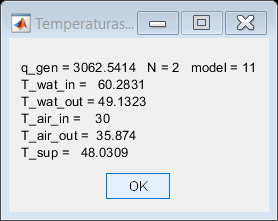


%Representación gráfica de la salida
%close all;
%plot(N_wat,T_wat_in);
% hold on; grid on;
% plot(T_wat_in,T_wat_out);
% plot(T_wat_in,T_sup);
% legend('Twi','Two','Ts');
%hold off;

hv_figure_all = findall(0, 'Type', 'Figure');
delete( hv_figure_all( arrayfun(@(h) contains(h.Tag, 'Msgbox'), hv_figure_all) ) )
message=[strcat("q_gen = ",num2str(q_gen),"   N = ",num2str(N),"   model = ",num2str(choice));
         strcat("T_wat_in =   ",num2str(T_wat_in));
         strcat("T_wat_out = ",num2str(T_wat_out));
         strcat("T_air_in =    ",num2str(T_air_in));
         strcat("T_air_out =  ",num2str(T_air_out));
         strcat("T_sup =   ",num2str(T_sup))];

msgbox(message,"Temperaturas obtenidas");

close all;
figure;
s1=surf(N_wat,Q_wat,T_wat_in,'FaceAlpha',0.5);grid on;
%s1.EdgeColor = 'none';
% s2=mesh(Q_wat,u_air',T_wat_in);grid on;
% s2.EdgeColor = 'none';
zlim("tight");xlim("tight");ylim("tight");
hold on;
%s2=surf(Q_wat,u_air',T_wat_out);grid on;
%s2.EdgeColor = 'none';
xlabel("N_{wat}");ylabel("q_{wat}");zlabel("T_{wat}");
legend("T_{wat out}","T_{wat in}")

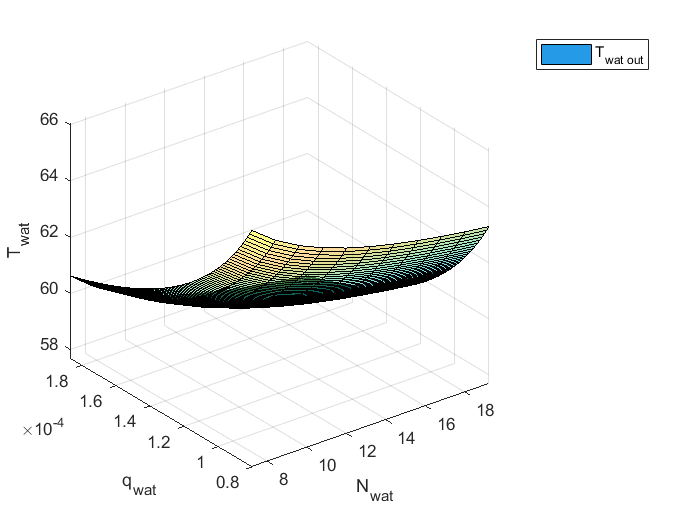

hold off;






%RECORDATORIO CRITERIOS DE VALIDEZ DE OPERACIÓN (NORMATIVA/DATASHEET):
%Temperatura máxima fluido en inversor: 65ºC
%Temperatura máxima fluido entrada motor: 50ºC

%Gráfica para la convergencia de los datos, con casos de valores inciales
%de interación diferentes. Se guardan los datos en vectores 
